I1 = imread('cameraman.tif');
I2 = imread('Images/I2.jpg');

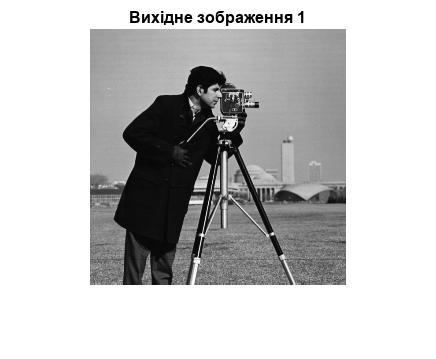

imshow(I1);
title('Вихідне зображення 1');

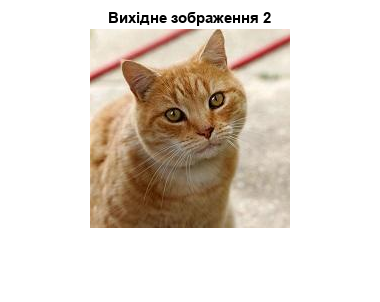

imshow(I2);
title('Вихідне зображення 2');

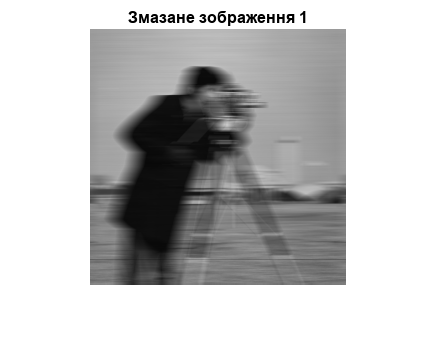

LEN = 21;
THETA = 0;
PSF1 = fspecial('motion', LEN, THETA);
blurred1 = imfilter(I1, PSF1, 'conv', 'circular');
imshow(blurred1);
title('Змазане зображення 1');

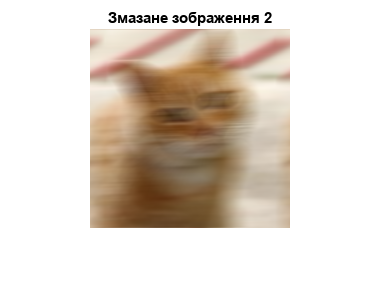

LEN = 30;
THETA = 2;
PSF2 = fspecial('motion', LEN, THETA);
blurred2 = imfilter(I2, PSF2, 'conv', 'circular');
imshow(blurred2);
title('Змазане зображення 2');

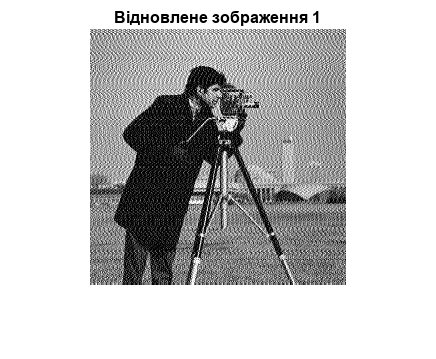

wnr1 = deconvwnr(blurred1, PSF1, 0);
imshow(wnr1);
title('Відновлене зображення 1');

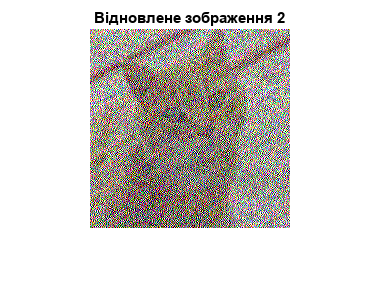

wnr2 = deconvwnr(blurred2, PSF2, 0);
imshow(wnr2);
title('Відновлене зображення 2');

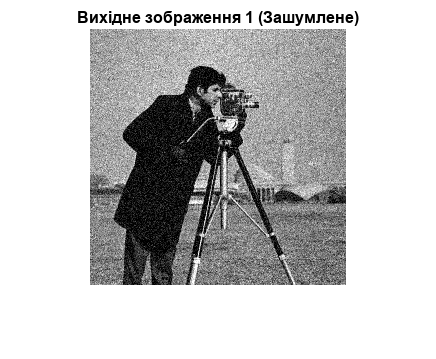

J1 = imnoise(I1,'gaussian');
imshow(J1);
title('Вихідне зображення 1 (Зашумлене)');

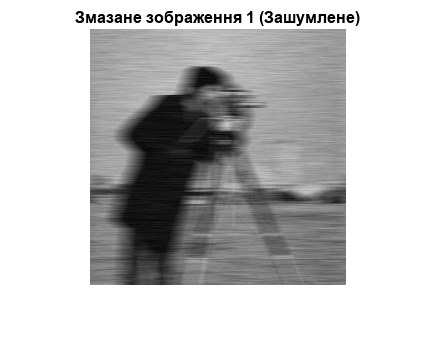

blurred3 = imfilter(J1, PSF1, 'conv', 'circular');
imshow(blurred3);
title('Змазане зображення 1 (Зашумлене)');

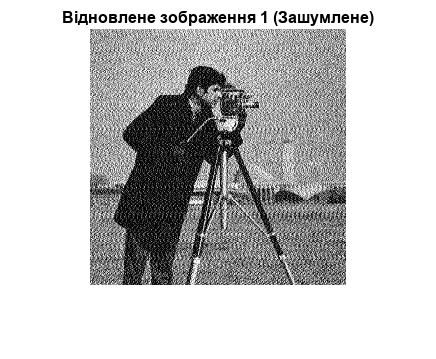

wnr3 = deconvwnr(blurred3, PSF1, 0);
imshow(wnr3);
title('Відновлене зображення 1 (Зашумлене)');